% Load the data from the Excel file
data = readtable('data.xlsx');

% Remove rows where the electric beam current is negative
mask = data{:, 3} >= 0;
data = data(mask, :);

mask = data{:,2} <= 50 & data{:,2}>=0; % mm
data = data(mask, :);

energy_loss = data{:,7}-data{:,8};

mask = energy_loss>0.4 & energy_loss<0.6;
data = data(mask,:);

% Extract the electric beam current and particle/beam charge columns
electric_current = data{:,3}.*1e-6; % in amperes
particle_beam_charge = data{:,4}; % in number of e
e = 1.60217662e-19; % Coulombs

% Cluster r_para values using k-means
r_para = data{:, 2}; % mm

silhouette_scores = [];
K = 5;

% Convert r_para into an n-by-1 matrix
r_para_matrix = r_para(:);

for k = 2:K
    [idx, ~] = kmeans(r_para_matrix, k);
    silhouette_scores(k) = mean(silhouette(r_para_matrix, idx));
end

% Find optimal number of clusters
[~, k_opt] = max(silhouette_scores);
fprintf('Optimal number of clusters: %d\n', k_opt);

Optimal number of clusters: 3


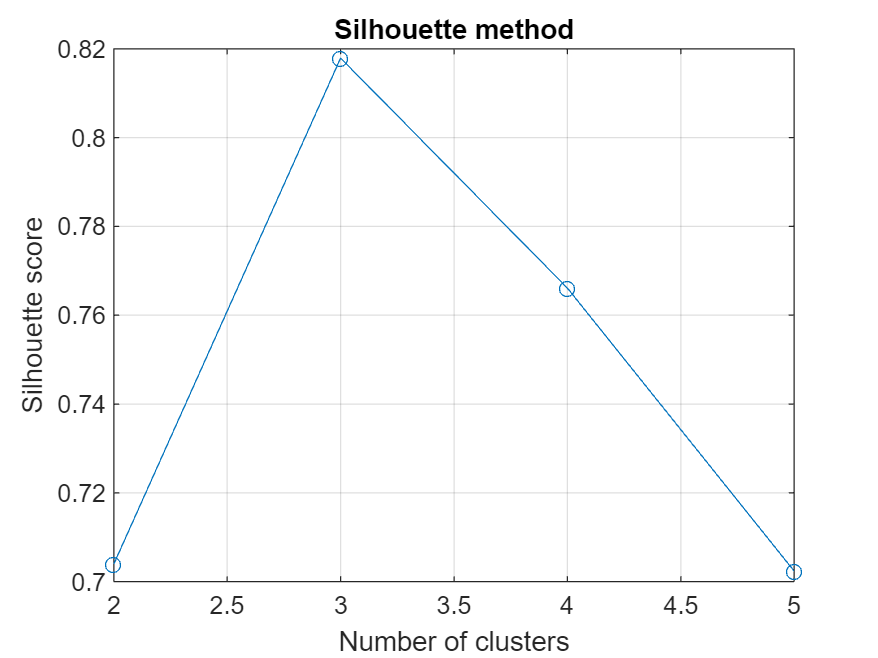


% Perform final k-means clustering with optimal number of clusters
[idx, centers] = kmeans(r_para_matrix, k_opt);

% Determine inner and outer radii for each annulus
inner_radii = zeros(k_opt, 1);
outer_radii = zeros(k_opt, 1);
for i = 1:k_opt
    mask = (idx == i);
    inner_radii(i) = min(r_para(mask));
    outer_radii(i) = max(r_para(mask));
end

% Compute the area of each annulus region
area = pi*(outer_radii.^2 - inner_radii.^2);

% Plot silhouette scores
figure;
plot(2:K, silhouette_scores(2:end), '-o');
xlabel('Number of clusters');
ylabel('Silhouette score');
title('Silhouette method');
grid on;

inner_radii = sort(inner_radii);
outer_radii = sort(outer_radii);


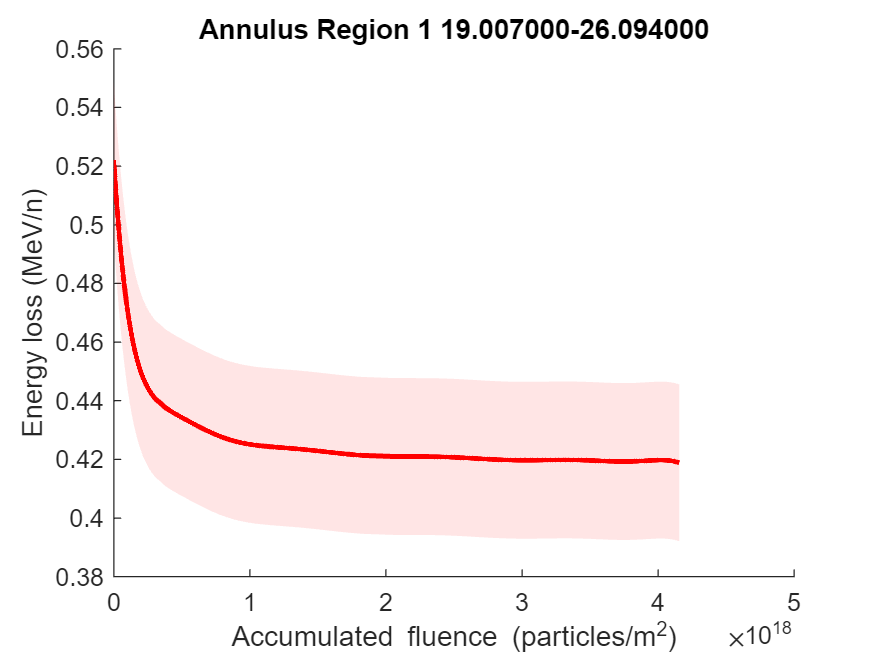

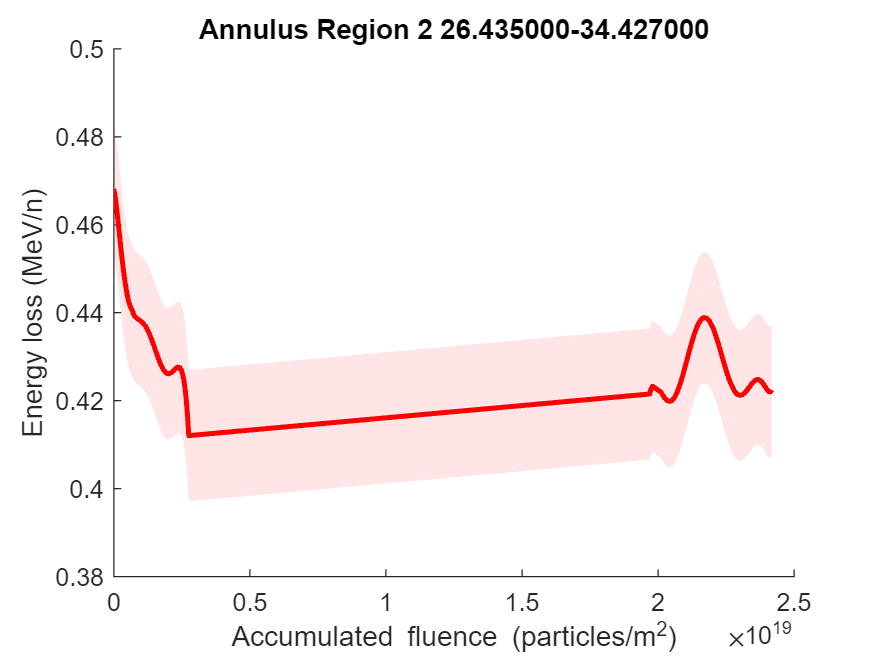

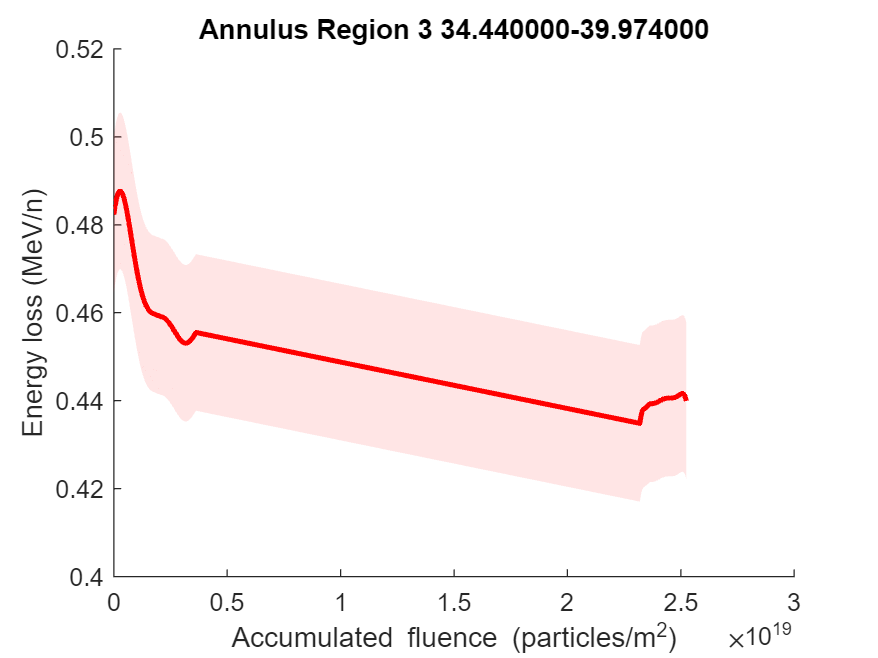

% Constants
e = 1.602176634e-19; % Elementary charge, C

for i = 1:k_opt
    % Filter data based on inner and outer radii
    mask = (r_para >= inner_radii(i)) & (r_para <= outer_radii(i));
    annulus_data{i} = data(mask, :);
    charge = annulus_data{i}{:, 4};
    G = annulus_data{i}{:, 7};
    H = annulus_data{i}{:, 8};
    energy_loss = (G - H);
    
    % Calculate the particle per second for the current annulus region
    particle_per_second = electric_current(mask)./(e .* charge); % particles/s

    % Calculate the time differences between each time stamp in seconds
    time_diff = seconds(diff(annulus_data{i}{:, 1}));
    time_diff(isnan(time_diff)) = 0;

    % Pad time_diff array with an additional zero at the beginning
    time_diff = [0; time_diff];

    % Calculate the area of the current annulus region
    area = pi * (outer_radii(i)^2 - inner_radii(i)^2)/1e6;

    % Calculate the cumulative fluence for the current annulus region
    fluence_rate = particle_per_second .* time_diff;
    fluence{i} = cumsum(fluence_rate) / area;

    % Fit a 3rd order polynomial
    p = polyfit(fluence{i}, energy_loss, 13);
    trendline = polyval(p, fluence{i});
    
    % Calculate the standard deviation
    std_dev = std(energy_loss);
    
    % Plot scatter plot
    figure;
    %scatter(fluence{i}, energy_loss);
    hold on;
    
    % Plot trendline
    plot(fluence{i}, trendline, 'r', 'LineWidth', 2);
    
    % Plot shaded region (using standard deviation)
    fill([fluence{i}; flipud(fluence{i})], [trendline + std_dev; flipud(trendline - std_dev)], ...
         'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    
    xlabel('Accumulated fluence (particles/m^2)');
    ylabel('Energy loss (MeV/n)');
    title(sprintf('Annulus Region %d %f-%f', i, inner_radii(i), outer_radii(i)));
    
    hold off;
end